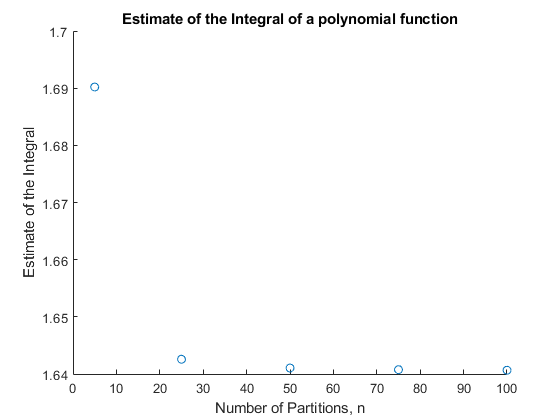

% MATLAB TEST 2 - 2019

% QUESTION 1
n = [5 25 50 75 100];
a = 0;
b = 0.8;
int_est = NaN(1, length(n));
for i = 1:length(n)
    int_est(i) = integrall(0, 0.8, n(i), @f);
end
scatter(n, int_est)
xlabel('Number of Partitions, n')
ylabel('Estimate of the Integral')
title('Estimate of the Integral of a polynomial function')
hold off

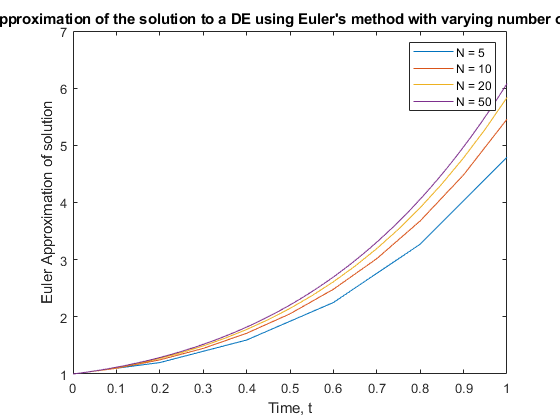




% QUESTION 2
T = 1;
N = [5 10 20 50];
y_0 = 1;
for i = 1:length(N)
    dt = T/N(i);
    t = 0 : dt : T;
    y = EMsolver(y_0, T, N(i));
    plot(t, y)
    hold on
end

xlabel('Time, t')
ylabel('Euler Approximation of solution')
title("Numerical approximation of the solution to a DE using Euler's method with varying number of time steps, N")
legend('N = 5', 'N = 10', 'N = 20', 'N = 50')

function [y] = f(x)
    y = 0.2 + (25.*x) - (200.*(x.^2)) + (675.*(x.^3)) - (900.*(x.^4)) + (400.*(x.^5));
end

function [int] = integrall(a, b, n, fn)
    dx = (b - a)/n;
    xi = (a + dx/2) : dx : b;
    rectangles = fn(xi) .* dx;
    int = sum(rectangles);
end
% QUESTION 1^^


% QUESTION 2
function [y] = EMsolver(y_0, T, N)
    dt = T/N;
    t = 0 : dt : T;
    SOL = NaN(1, length(t));
    SOL(1) = y_0;
    for i = 2:length(t)
        m = (1 + 4*t(i-1))*sqrt(SOL(i-1));
        SOL(i) = SOL(i-1) + dt*m;
    end
    y = SOL;
end